clear ;
close all;

load ryan2_gen_data_new.mat

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

[https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets](https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets)

`Total     = Design + Nondesign`

` Design    = Training + Validation`

` Nondesign = Testing`

` Total       = Training + Nontraining`

` Nontraining = Validation + Testing`

` Overfitting: Using more ``weights and biases than necessary`

` Overtraining: Improving the ``performance of the training data at the expense of deteriorating the performance`

` on ``nontraining data`

` Training ``data subset: Used to DIRECTLY estimate weights and biases. Performance estimates are BIASED.`

` Validation ``data subset: Used to `

` (1) determine ``when overtraining an overfit net begins to occur AND `

` (2) rank ``multiple designs. `

` Performance ``estimates are SIGNIFICANTLY LESS BIASED than training data estimates.`

` Test data subset: Used to obtain UNBIASED ESTIMATES of performance on nontraining (INCLUDING UNSEEN!) data`

[https://kr.mathworks.com/help/deeplearning/ref/dividerand.html](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html)

`[`[`trainInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_1728d793-edc6-4595-8a0d-22992dffe813)`,`[`valInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_caf766f1-5912-45f0-919e-f903b9d313f4)`,`[`testInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_8e6cbc0b-a46a-4dbf-b95c-5eb6fcd46e9b)`] = dividerand(`[`Q`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_a6062bcf-a3b1-4224-9caa-fa872fae85d3)`,`[`trainRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_72c9b34e-a329-46f2-a907-39b169c6e19a)`,`[`valRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_2abef95f-2bd8-4aec-8a09-126cd5c93bcc)`,`[`testRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_f4192d38-e08b-446c-af8a-ee0cc9472af8)`)`는 나눌 목표값의 개수, 훈련에 사용할 벡터의 비율, 검증에 사용할 벡터의 비율, 테스트에 사용할 벡터의 비율을 받고, 훈련 인덱스, 검증 인덱스, 테스트 인덱스를 반환합니다

[https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html](https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html)

훈련, 테스트 및 검증의 디폴트 비율은 각각 0.7, 0.15, 0.15입니다.

[https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html)

베이즈 정규화는 함수 [`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)에 구현되어 있습니다. 다음 코드는 이 함수를 사용하여 1-20-1 신경망이 [얕은 신경망 일반화를 개선하고 과적합 방지하기](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html) 항목의 그림에 나와 있는 잡음이 있는 사인파를 근사하도록 훈련시키는 방법을 보여줍니다. ([`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)의 영향이 조기 중지로부터 격리되도록 `net.divideFcn`을 설정하여 데이터 분할이 취소되었습니다.)

`x = -1:0.05:1;`

`t = sin(2*pi*x) + 0.1*randn(size(x));`

`net = feedforwardnet(20,'trainbr');`

`net = train(net,x,t);`

xnorm = new_xnormall;
ynorm = new_ynormall;

- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = new_idxTrainRand;
netFNN1_1.divideParam.valInd = new_idxValidRand;
netFNN1_1.divideParam.testInd = new_idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%tr


netFNN1_2 = feedforwardnet(50); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = new_idxTrainRand;
netFNN1_2.divideParam.valInd = new_idxValidRand;
netFNN1_2.divideParam.testInd = new_idxTestRand; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = new_idxTrainRand;
netFNN1_3.divideParam.valInd = new_idxValidRand;
netFNN1_3.divideParam.testInd = new_idxTestRand; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_3, tr] = train(netFNN1_3, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.



netFNN2_1 = feedforwardnet([50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
[netFNN2_1, tr2] = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([100,50]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
netFNN2_2 = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([100,50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
netFNN3_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_1)

netFNN4_1 = feedforwardnet([100,50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
netFNN4_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');
%view(netFNN3_1)

netFNN5_1 = feedforwardnet([100,70,50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
netFNN5_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');
%view(netFNN3_1)

pFNN1_1 = netFNN1_1(xnorm(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm(tr.testInd, :)');
pFNN2_1 = netFNN2_1(xnorm(tr.testInd, :)');
pFNN2_2 = netFNN2_2(xnorm(tr.testInd, :)');
pFNN3_1 = netFNN3_1(xnorm(tr.testInd, :)');
pFNN4_1 = netFNN4_1(xnorm(tr.testInd, :)');
pFNN5_1 = netFNN5_1(xnorm(tr.testInd, :)');

ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
pFNN1_2_hat = pFNN1_2 * yrate + ymin;
pFNN1_3_hat = pFNN1_3 * yrate + ymin;
pFNN2_1_hat = pFNN2_1 * yrate + ymin;
pFNN2_2_hat = pFNN2_2 * yrate + ymin;
pFNN3_1_hat = pFNN3_1 * yrate + ymin;
pFNN4_1_hat = pFNN4_1 * yrate + ymin;
pFNN5_1_hat = pFNN5_1 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 163.5404

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))
rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))
rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))
rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))
rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN1_2_hat = 171.5929

rmse_pFNN1_3_hat = 211.3626

rmse_pFNN2_1_hat = 81.4723

rmse_pFNN2_2_hat = 81.4723

rmse_pFNN3_1_hat = 46.1369

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 46.1369

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 46.1369

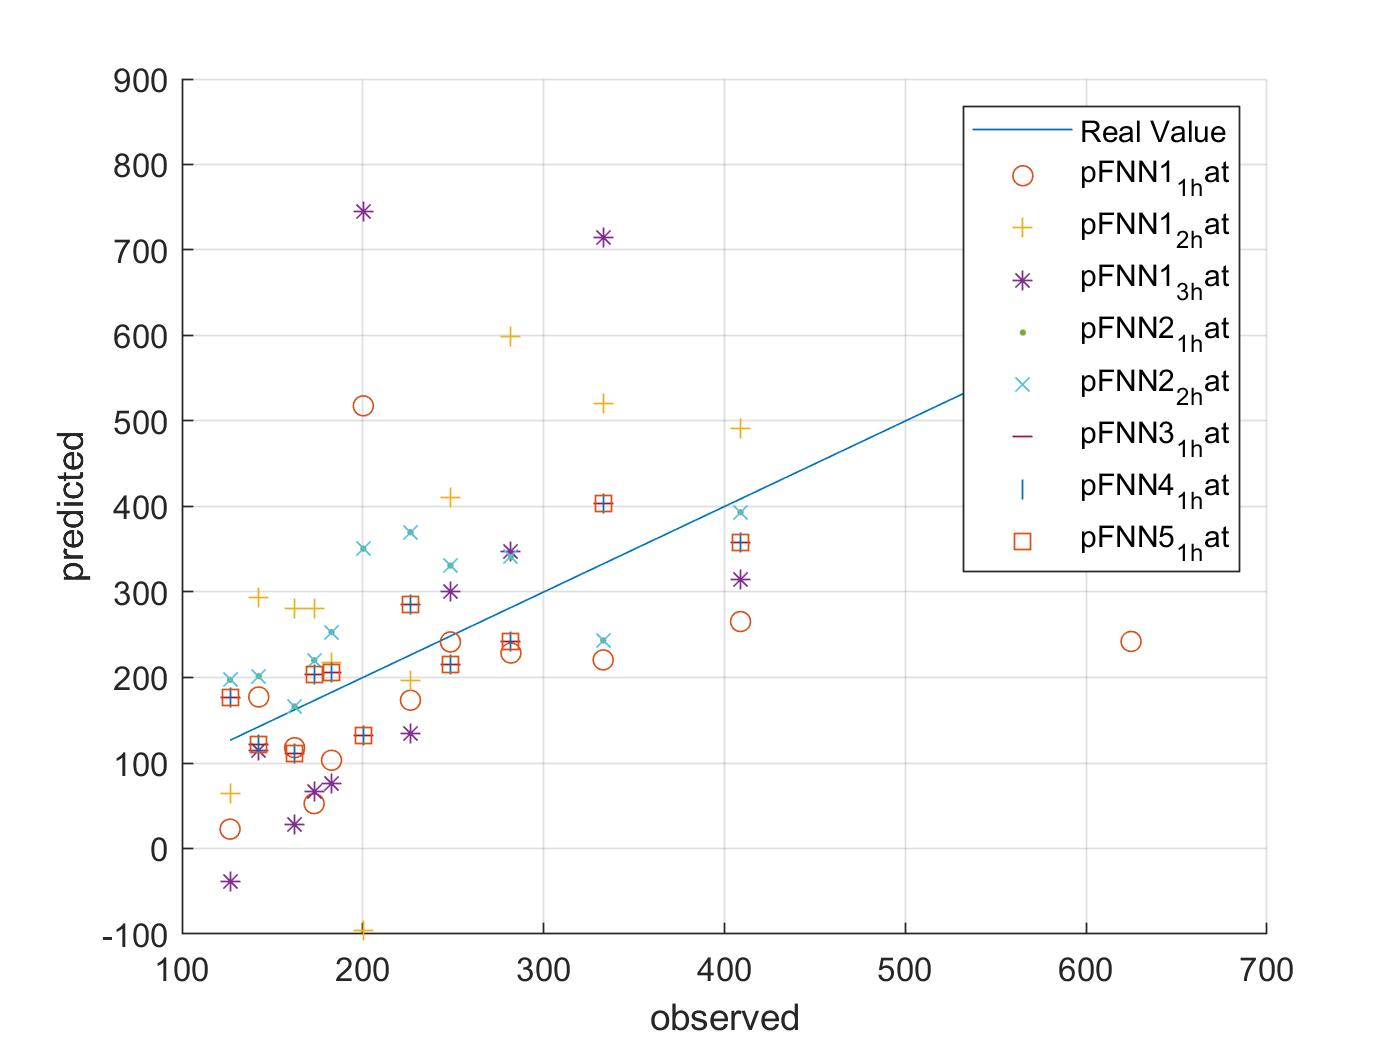


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 

		'pFNN4_1_hat', ... 
		'pFNN5_1_hat')



ryan2_gen_data_model_new_desc = 'ryan2_gen_data_model_new';
save('ryan2_gen_data_model_new.mat','ryan2_gen_data_model_new_desc')
save('ryan2_gen_data_model_new.mat','netFNN1_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN1_2' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN1_3' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN2_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN2_2' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN3_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN4_1' ,'-append')
save('ryan2_gen_data_model_new.mat','netFNN5_1' ,'-append')

pFNN1_1_self = netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_1_self = netFNN2_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_2_self = netFNN2_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN3_1_self = netFNN3_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN4_1_self = netFNN4_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN5_1_self = netFNN5_1(xnorm([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
pFNN1_2_self_hat = pFNN1_2_self * yrate + ymin;
pFNN1_3_self_hat = pFNN1_3_self * yrate + ymin;
pFNN2_1_self_hat = pFNN2_1_self * yrate + ymin;
pFNN2_2_self_hat = pFNN2_2_self * yrate + ymin;
pFNN3_1_self_hat = pFNN3_1_self * yrate + ymin;
pFNN4_1_self_hat = pFNN4_1_self * yrate + ymin;
pFNN5_1_self_hat = pFNN5_1_self * yrate + ymin;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 126.2132

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 168.6517

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 124.2480

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 105.6888

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 105.6888

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 69.3686

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 69.3686

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 69.3686

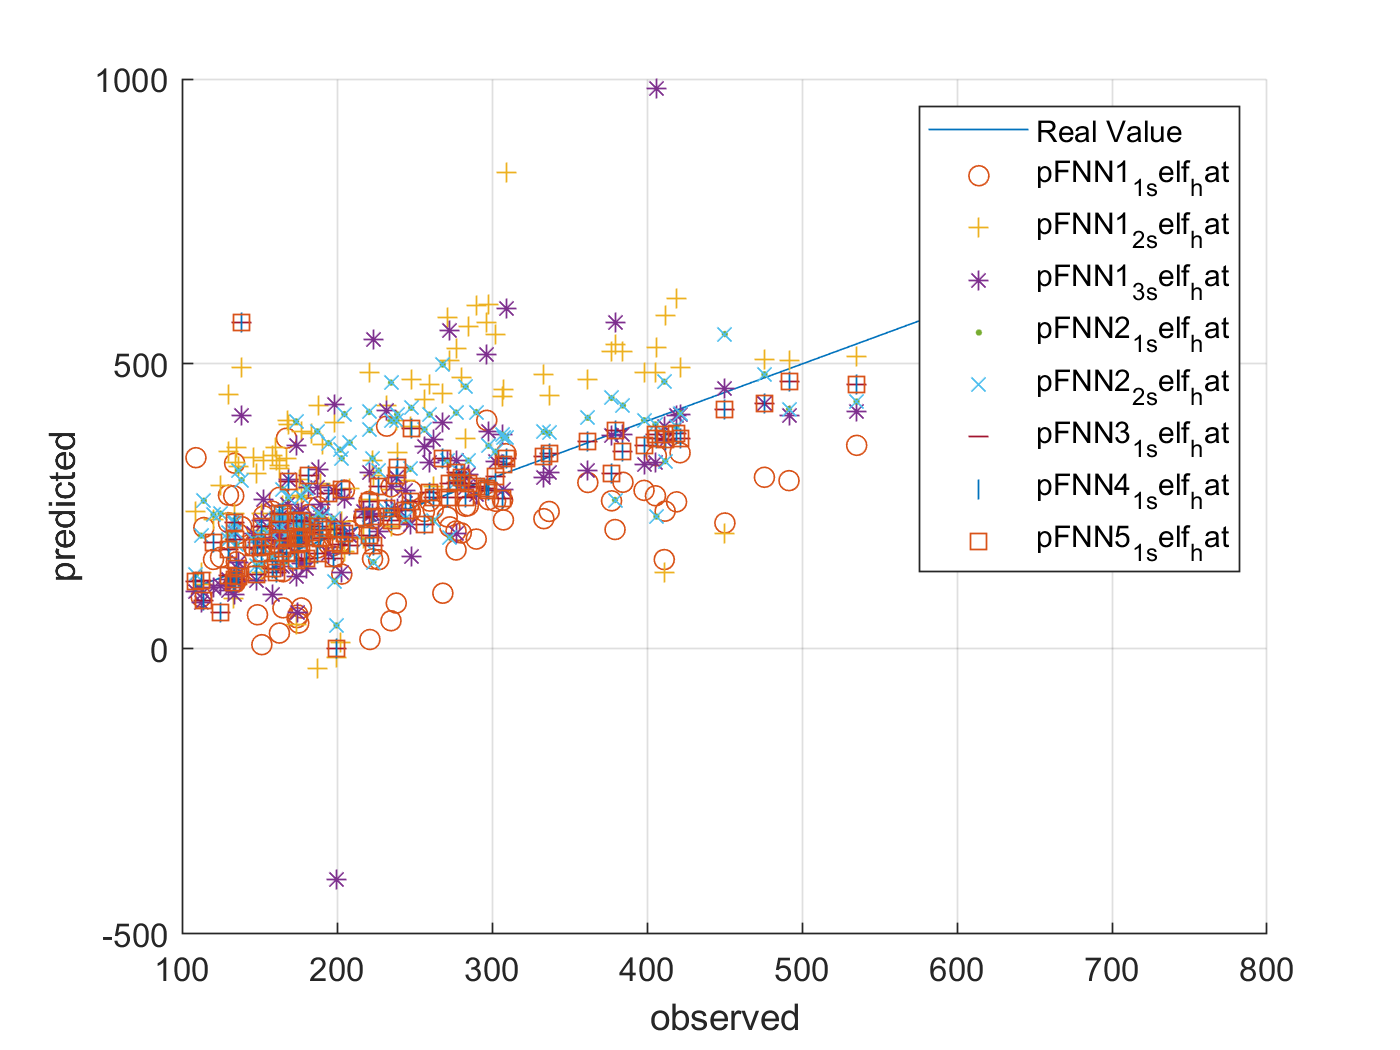



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat')